# EXERCISE A -- GUIDED STIFFNESS-METHOD TUTORIAL

Determine the horizontal displacement, vertical displacement and rotation at node 1. The horizontal beam is 3 m long; the right column is 4 m high and fixed at node 3. Node 2 is a rigid corner. At node 1, apply 18 kN left and 27 kN down.

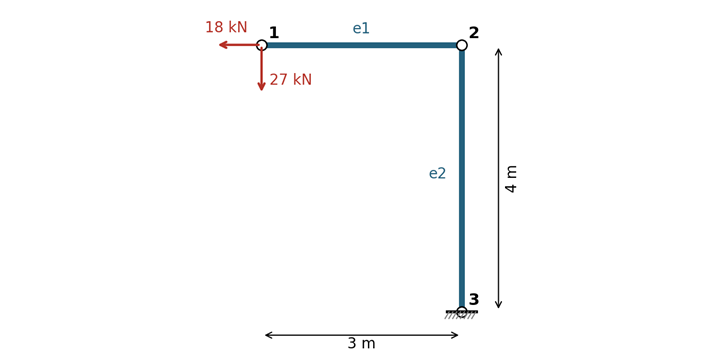

## 0. Prepare the workspace and display options

clear removes previous variables; clc clears the Command Window; close all closes earlier figures. Execute this section once at the START. showMatrices controls intermediate output, makePlots controls visualization, and deformationScale=0 requests automatic visual magnification. These switches do not change the structural solution.

clear; clc; close all;
format short g;
showMatrices = true;   % Show element matrices and assembled equations.
makePlots = true;      % Set false for numerical calculations only.
deformationScale = 0;  % Zero selects an automatic visual magnification.

## Exercise statement and modeling interpretation

Node 1: loaded free end; node 2: rigid corner; node 3: fixed base. Element 1 runs 1 -> 2 (right); element 2 runs 2 -> 3 (down).

## 1. Define material and section properties

PURPOSE: establish axial rigidity EA and bending rigidity EI. Convert 200 GPa to 200000 N/mm^2. All dimensions are entered in mm. A is cross-sectional area in mm^2; I is the second moment of area in mm^4 about the out-of-plane bending axis. Every member has the same properties, so scalar E, A and I are sufficient for these exercises.

## 2. Define node coordinates and member connectivity

PURPOSE: describe the frame as joints connected by straight members. Each row of nodes is [x y] in mm, and its row number is the node number. Each row of elements is [i j], and its row number is the element number. The i->j order defines local axes and signs; it does not change the physical frame if all associated local quantities are transformed consistently.

## 3. Associate each motion with a global equation number

PURPOSE: connect physical nodal motions with positions in the solution vector. dofMap(n,:)=[index_ux index_uy index_theta] at node n. For example, d(dofMap(n,1)) returns node n's horizontal displacement. Every global index appears once. Connectivity uses NODE numbers, whereas stiffness assembly uses DOF numbers: do not confuse these two lists.

## 4. Define the support restraints

PURPOSE: distinguish known motions from unknown motions. Node 3 is fixed: horizontal translation, vertical translation and rotation are all zero. Therefore constrain DOFs 7,8,9, leaving six unknown DOFs. prescribedValues has the same order as fixedDofs.

## 5. Define loads and their coordinate directions

PURPOSE: build a column vector of concentrated nodal actions. Force entries are in N; rotation-DOF entries are applied couples in N*mm. Node 1: 18 kN left -> F1=-18000 N; 27 kN down -> F2=-27000 N. The numbered DOF arrows in the figure are not extra applied loads. qLocal stores member loads per unit length; all are zero in this exercise. Stage 8 retains the general distributed-load procedure and gives zero vectors.

EXERCISE A: displacements at node 1


Global signs: right/up/CCW positive. Internal units: N, mm, rad.


## 6. Determine element lengths, orientations and global DOF lists

PURPOSE: turn geometry into element information. For a member i->j: dx=xj-xi; dy=yj-yi; L=sqrt(dx^2+dy^2); c=dx/L; s=dy/L. c and s are direction cosines. Local x points from i to j; local y is 90 degrees counterclockwise from local x. edofs gives the six GLOBAL indices of this element in endpoint order. elementData stores one record per member, with named fields.


Element 1: node 1 -> 2, L = 3000 mm, c = 1.0, s = 0.0


Element DOFs: 1 2 3 4 5 6 



Element 2: node 2 -> 3, L = 4000 mm, c = 0.0, s = -1.0


Element DOFs: 4 5 6 7 8 9 


## 7. Calculate the local stiffness and transform it to global axes

PURPOSE: combine axial and bending behavior in a common coordinate system. The included frameElement function gives the full 6-by-6 matrix. Its axial terms contain EA/L. Its bending terms contain 12EI/L^3, 6EI/L^2, 4EI/L and 2EI/L. A frame transmits bending moments as well as axial forces; a truss model would omit the bending behavior.

ELEMENT RELATION without member loading: qLocalEnd=kLocal*dLocal. dLocal=T*dGlobal; qGlobalEnd=T'*qLocalEnd. Consequently kGlobal=T'*kLocal*T. For each node [u;v]=[c s;-s c]*[ux;uy]; the z rotation is unchanged. Transforming forces with T' preserves virtual work in the two systems. MATLAB .' is transpose without complex conjugation.


ELEMENT 1 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
      8.6e+05            0            0     -8.6e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
     -8.6e+05            0            0      8.6e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10



Transformation T:
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
      8.6e+05            0            0     -8.6e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
     -8.6e+05            0            0      8.6e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10




ELEMENT 2 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
     6.45e+05            0            0    -6.45e+05            0            0
            0        11250     2.25e+07            0       -11250     2.25e+07
            0     2.25e+07        6e+10            0    -2.25e+07        3e+10
    -6.45e+05            0            0     6.45e+05            0            0
            0       -11250    -2.25e+07            0        11250    -2.25e+07
            0     2.25e+07        3e+10            0    -2.25e+07        6e+10



Transformation T:
     0    -1     0     0     0     0
     1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0    -1     0
     0     0     0     1     0     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
        11250            0     2.25e+07       -11250            0     2.25e+07
            0     6.45e+05            0            0    -6.45e+05            0
     2.25e+07            0        6e+10    -2.25e+07            0        3e+10
       -11250            0    -2.25e+07        11250            0    -2.25e+07
            0    -6.45e+05            0            0     6.45e+05            0
     2.25e+07            0        3e+10    -2.25e+07            0        6e+10



## 8. Convert distributed member loading into equivalent nodal actions

PURPOSE: represent continuous loading in the nodal equilibrium equations. For uniform local loads qx and qy (N/mm), the CONSISTENT load vector is: [qx*L/2; qy*L/2; qy*L^2/12; qx*L/2; qy*L/2; -qy*L^2/12]. It follows from integrating the load against the element shape functions. Two transverse forces alone can balance the resultant but do not preserve virtual work for arbitrary nodal rotations: include the end moments too. These equivalent actions are not the unknown support reactions. The global equivalent vector is fGlobal=T'*fLocal.


ELEMENT 1 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0




ELEMENT 2 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0



## 9. Assemble the global stiffness matrix and load vector

PURPOSE: combine member equations while enforcing joint compatibility. K begins as an nDof-by-nDof zero matrix; F begins with concentrated loads. K(edofs,edofs) selects the element's 6-by-6 contribution within the frame. ADD each transformed matrix and load vector; do not overwrite existing contributions at a shared joint. Shared nodal translations and rotations enforce compatibility between connected members and their rigid joint. The full K has rigid-body modes before support restraints are applied. We therefore solve the reduced restrained system, not K*d=F directly.

ASSEMBLED K:
      8.6e+05            0            0     -8.6e+05            0            0            0            0            0
            0        26667        4e+07            0       -26667        4e+07            0            0            0
            0        4e+07        8e+10            0       -4e+07        4e+10            0            0            0
     -8.6e+05            0            0   8.7125e+05            0     2.25e+07       -11250            0     2.25e+07
            0       -26667       -4e+07            0   6.7167e+05       -4e+07            0    -6.45e+05            0
            0        4e+07        4e+10     2.25e+07       -4e+07      1.4e+11    -2.25e+07            0        3e+10
            0            0            0       -11250            0    -2.25e+07        11250            0    -2.25e+07
            0            0            0            0    -6.45e+05            0            0     6.45e+05            0
            0            0            0    

ASSEMBLED F:
      -18000
      -27000
           0
           0
           0
           0
           0
           0
           0



## 10. Partition the equations using the support conditions

PURPOSE: solve only for motions that are genuinely unknown. Let f mean free and c mean constrained: Kff*df+Kfc*dc=Ff, so Kff*df=Ff-Kfc*dc. setdiff finds all DOFs not listed in fixedDofs. Initialize the complete d, insert prescribed support motions dc, and extract Kff and rhs in freeDofs order. Here dc=0; retaining Kfc*dc also supports imposed nonzero motions.

## 11. Check stability and solve for the free displacements

PURPOSE: obtain the unique elastic solution of the restrained frame. K must be symmetric. Kff should be positive definite for this stable model; chol returns a nonzero flag if that property is absent. MATLAB backslash solves the linear system without explicitly forming inv(Kff). Insert the solved free motions into their original positions in d.


ASSEMBLED SYSTEM


Full K (mixed force/moment and translation/rotation units):
      8.6e+05            0            0     -8.6e+05            0            0            0            0            0
            0        26667        4e+07            0       -26667        4e+07            0            0            0
            0        4e+07        8e+10            0       -4e+07        4e+10            0            0            0
     -8.6e+05            0            0   8.7125e+05            0     2.25e+07       -11250            0     2.25e+07
            0       -26667       -4e+07            0   6.7167e+05       -4e+07            0    -6.45e+05            0
            0        4e+07        4e+10     2.25e+07       -4e+07      1.4e+11    -2.25e+07            0        3e+10
            0            0            0       -11250            0    -2.25e+07        11250            0    -2.25e+07
            0            0            0            0    -6.45e+05            0            0     6.45e+05          

Equivalent global load vector F:
      -18000
      -27000
           0
           0
           0
           0
           0
           0
           0



Free DOFs, in reduced-system order:
     1     2     3     4     5     6



Reduced stiffness Kff:
      8.6e+05            0            0     -8.6e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
     -8.6e+05            0            0   8.7125e+05            0     2.25e+07
            0       -26667       -4e+07            0   6.7167e+05       -4e+07
            0        4e+07        4e+10     2.25e+07       -4e+07      1.4e+11



Reduced right-hand side:
      -18000
      -27000
           0
           0
           0
           0



## 12. Recover reactions and organize the nodal displacements

PURPOSE: substitute the solved motions into the FULL unreduced equations. R=K*d-F gives support reactions at constrained DOFs and numerical zeros at free DOFs. F must include equivalent member loads as well as point loads. d(dofMap.') gathers entries in node order; reshape and transpose produce one row per node: [ux uy theta]. The table reports mm, mm and radians.


NODAL DISPLACEMENTS (positive right/up/CCW)


    Node    DOF_ux    DOF_uy    DOF_theta     ux_mm      uy_mm      theta_rad
    ____    ______    ______    _________    _______    ________    _________

     1        1         2           3        -17.221     -27.492    0.009825 
     2        4         5           6          -17.2    -0.04186      0.0078 
     3        7         8           9              0           0           0 



## 13. Display the support reactions in kN and kN*m

PURPOSE: extract support-node actions and convert from internal units. Divide N by 1000 and N*mm by 1000000. Reactions act FROM the support ON the frame; positive means right/up/CCW. A downward vertical pin reaction means that the support must hold the frame down: uplift demand on anchorage. Pin moment entries are free-DOF residuals and should be numerical zero.

SUPPORT REACTIONS (positive right/up/CCW)


    Node    Rx_kN    Ry_kN    Mz_kNm
    ____    _____    _____    ______

     3       18       27       -153 



## 14. Recover axial force, shear force and moment at each member end

PURPOSE: obtain the actions applied TO each member at its two ends. Extract its six global displacements; transform them by dLocal=T*dGlobal. Then qEnd=kLocal*dLocal-fLocal. Subtracting the consistent load vector accounts for load-induced fixed-end actions. kLocal*dLocal alone is wrong for a member with distributed loading. Order is [Ni Vi Mi Nj Vj Mj]; both end moments are positive CCW. These endpoint actions use a different convention from opposite-face signs often chosen for internal force diagrams; do not equate their signs directly.

LOCAL END ACTIONS applied TO each member, in its local axes


Order: [Ni Vi Mi Nj Vj Mj]; moments positive CCW at both ends.


These are end actions, not a bending-diagram sign convention.


    Element    Ni_kN    Vi_kN      Mi_kNm      Nj_kN    Vj_kN    Mj_kNm
    _______    _____    _____    __________    _____    _____    ______

       1        -18      -27     5.9605e-14      18      27        -81 
       2         27      -18             81     -27      18       -153 



## 15. Check free-DOF equilibrium and whole-frame static balance

PURPOSE: verify sum(Fx)=0, sum(Fy)=0 and sum(M_origin)=0. A force at [x,y] contributes moment x*Fy-y*Fx. Here a uniform load is represented by its physical resultant at the member centroid, independently of the equivalent nodal loading used to solve the system. Numerical roundoff is normal; assert stops if a tolerance is exceeded.

Equilibrium residual: Fx = 2.619e-10 N, Fy = 0.000e+00 N, M = -9.090e-07 N*mm


## 16. Compare with an independent analytical solution

PURPOSE: verify the matrix result using cantilever formulas / virtual work. B is beam length, H column height, P leftward-load magnitude, Q downward-load magnitude. The column top carries horizontal load P and a CCW couple Q*B. They give theta2=(P*H^2/2+Q*B*H)/(E*I). ux1 combines column bending under P, bending under Q*B, and beam shortening. uy1 combines column axial shortening, corner rotation -B*theta2, and beam bending deflection. Tip rotation adds beam bending rotation to theta2. EXPECTED: ux1=-17.22093023 mm; uy1=-27.49186047 mm; theta1=+0.009825 rad, counterclockwise.


REQUESTED ANSWER -- NODE 1


ux1    = -17.22093023 mm  (negative = left)


uy1    = -27.49186047 mm  (negative = down)


theta1 = +0.009825000 rad = +0.562931 deg (positive = CCW)


Analytical and stiffness-method results agree.


## 17. Relate the solution to the magnified deformed shape

PURPOSE: see how nodal motion and member curvature combine. The model panel shows nodes, members, supports and loads in metres. The deformed panel magnifies small elastic motions; read its stated scale. Do not infer actual deflections from that magnified drawing. The included function uses Hermite bending shape functions, linear axial interpolation and uniform-load particular solutions. Joining displaced nodes with straight lines would hide curvature. The plot visualizes a linear solution, not a nonlinear analysis of the enlarged deformed geometry.

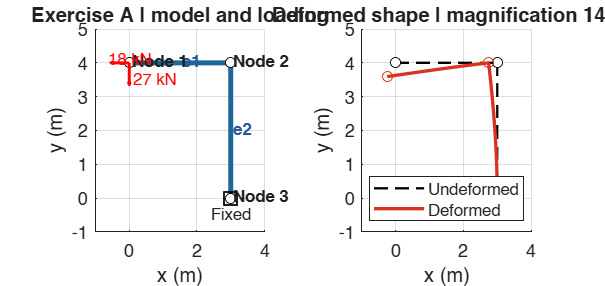

## 18. Classroom investigations and interpretation

Run the baseline model before experimenting. If loads or geometry change, update the analytical-check inputs consistently or skip that section. Suggested investigations: - Double E only: all displacements halve; reactions remain unchanged here. - Increase A only: identify the influence of axial flexibility. - Explain why full K has rigid-body modes but restrained Kff does not. - Reverse a member's node order and transform its local loads consistently; the global physical solution must remain unchanged. Exercise-specific discussion: - Why does a vertical load cause horizontal tip displacement? - Which contribution disappears if beam axial deformation is neglected? - Why is the tip rotation greater than the corner rotation?

Execute numbered sections in order, or run the whole file. The supporting local functions below are not additional exercise stages.

## LOCAL FUNCTIONS -- supporting routines